**0. Preparation**

clear, close all,clc

    Read raw source data

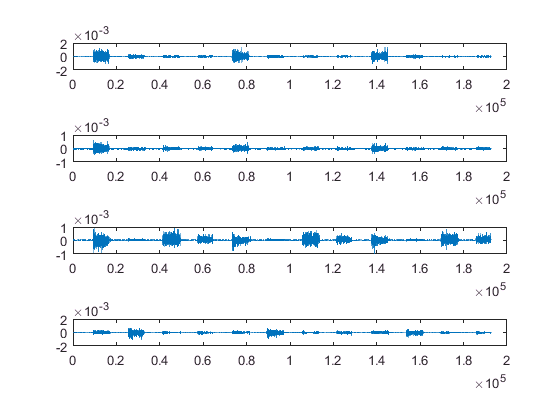

for ch=1:4
    sEMG_raw{ch} = load(['Channel', num2str(ch), '.txt']);
    % source data preview
    subplot(4,1,ch);
    plot(sEMG_raw{ch});
end

**1. Ch-1 Rawdata Preview**

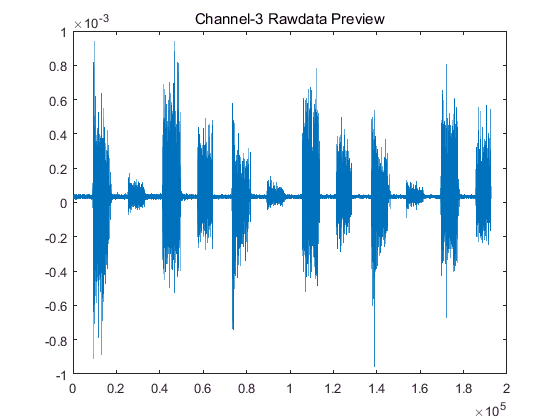

% Preview Ch-1 rawdata
nCh = 3;
figure;
plot(sEMG_raw{nCh})
title(['Channel-',num2str(nCh),' Rawdata Preview'])

**1.2 Part of Ch-1 Rawdata Preview**

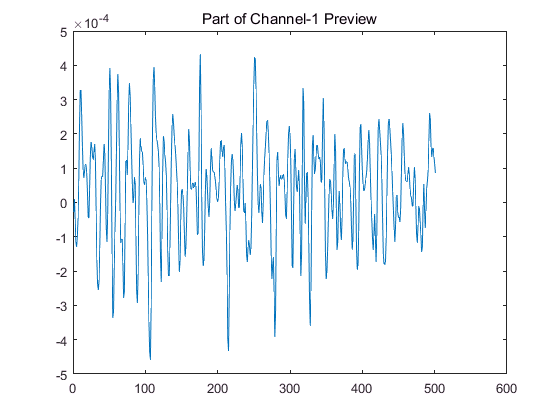

figure;
plot(sEMG_raw{nCh}(11000:11500));
title('Part of Channel-1 Preview');

**2. Kinds of Mother Wavelet Preview**

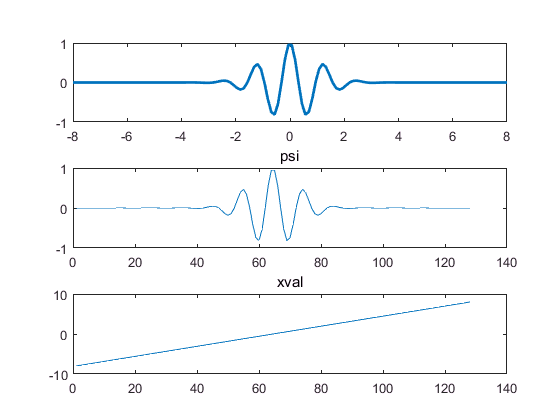

[psi, xval] = wavefun('morl',7);
figure;
subplot(3,1,1);
plot(xval, psi, 'linewidth', 2)
subplot(3,1,2);
plot(psi)
title('psi');
subplot(3,1,3);plot(xval);title('xval')

**2.1 Comparison on the same plot**

% Clipping part
figure;
subplot(3,1,1);plot(psi(64-20:64+20));title('part morl')
subplot(3,1,2);plot(sEMG_raw{1}(11030:11100)); title('part of rawdata');
subplot(3,1,3);
plot(sEMG_raw{1}(11031:11100));
ax = gca;
ax.YLim(2)

ans = 1.0000e-03

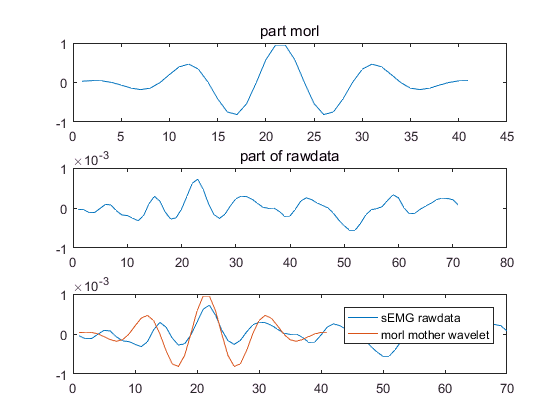

hold on;
plot(ax.YLim(2)*psi(64-20:64+20));
legend('sEMG rawdata', 'morl mother wavelet')

**3. Wave Detection in sEMG rawdata**

    3.1 Decomposition with wavelet transformation

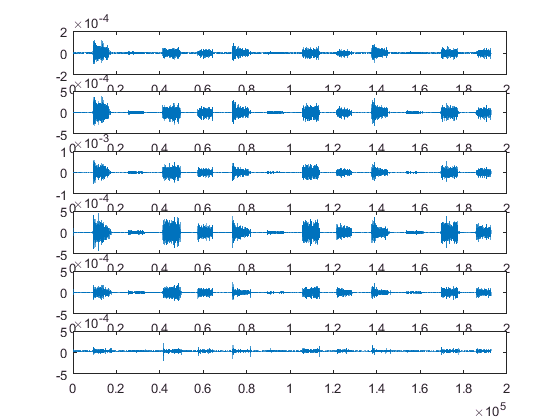

wt = modwt(sEMG_raw{nCh}, 5);
for n=1:size(wt,1)
    subplot(size(wt,1), 1,n);
    plot(wt(n,:))
end

3.2 reconstruction with part of decomposition levels result

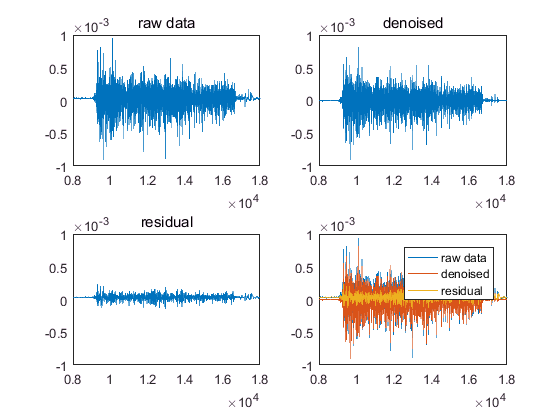

wtrec = zeros(size(wt));
wtrec(2:4, :) = wt(2:4, :); % only details of level [2,4] are considered.
xrec_ch1 = imodwt(wtrec, 'sym4');
figure;
subplot(2,2,1);plot(sEMG_raw{nCh});title('raw data');ax = gca;set(ax, 'XLim', [8000 18000])
YLimitation = ax.YLim;

subplot(2,2,2);plot(xrec_ch1); title('denoised');
ax = gca;set(ax, 'XLim', [8000 18000]); set(ax, 'YLim', YLimitation);
subplot(2,2,3);plot(sEMG_raw{nCh} - xrec_ch1'); title('residual');
ax = gca;set(ax, 'XLim', [8000 18000]);set(ax, 'YLim', YLimitation);

subplot(2,2,4);
plot(sEMG_raw{nCh}); hold on;
plot(xrec_ch1); hold on;
plot(sEMG_raw{nCh} - xrec_ch1'); hold on;
legend('raw data', 'denoised', 'residual');
ax = gca;
set(ax, 'XLim', [8000 18000]);set(ax, 'YLim', YLimitation);

**4. Clipping on manual**

RestPoints = 1e3*[1,   8; ...
                  18,  24; ...
                  35,  40; ...
                  52,  56; ...
                  65,  72; ...
                  83,  88; ...
                  100, 104; ...
                  115, 120; ...
                  130, 136; ...
                  147, 152; ...
                  164, 168; ...
                  180, 184];
Motion1Points = 1e3*[10, 16; ...
                     74, 80; ...
                     138,144];
Motion2Points = 1e3*[26, 32; ...
                     90, 96; ...
                     154,160];
Motion3Points = 1e3*[42, 48; ...
                     106,112; ...
                     170, 176];
Motion4Points = 1e3*[58, 64; ...
                     122,128; ...
                     187, 192];
% prepare receipt for clipped motion-parts data
% Rest
% Motion1
% Motion2
% Motion3
% Motion4
x = {[], [], [], [], []};

ClippedPoints = {RestPoints, Motion1Points, Motion2Points, Motion3Points, Motion4Points};

**4.1 **Clipp Rest parts

file 'Channel1.txt'

192645x1

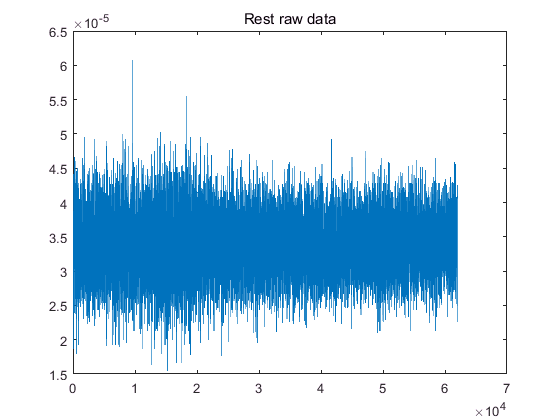

for n=1:size(RestPoints,1)
    x{1} = [x{1}; ...
            sEMG_raw{nCh}(RestPoints(n, 1):RestPoints(n,2))];
end
figure;plot(x{1}); title('Rest raw data');

  **4.2 Clipp Motion1 parts**

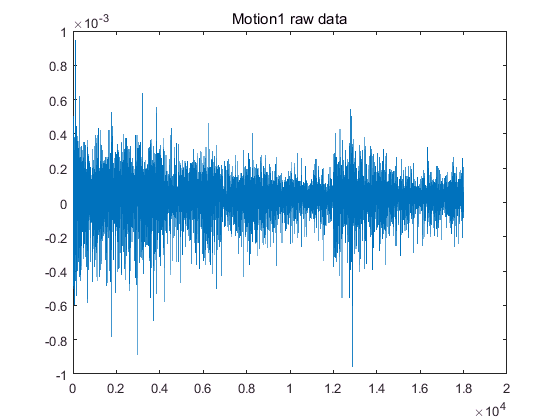

for n=1:size(Motion1Points,1)
    x{2} = [x{2}; ...
            sEMG_raw{nCh}(Motion1Points(n, 1):Motion1Points(n,2))];
end
figure;plot(x{2}); title('Motion1 raw data');

  **4.3 Clipp Motion2 parts**

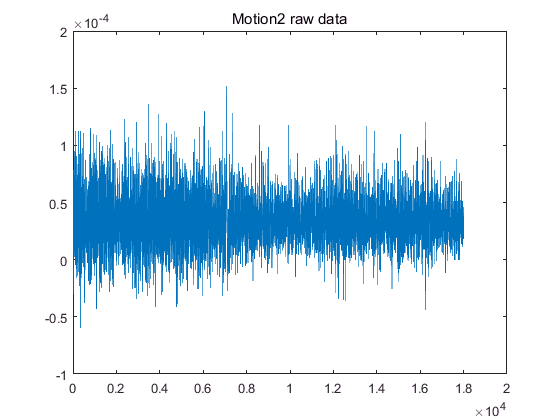

for n=1:size(Motion2Points,1)
    x{3} = [x{3}; ...
            sEMG_raw{nCh}(Motion2Points(n, 1):Motion2Points(n,2))];
end
figure;plot(x{3}); title('Motion2 raw data'); 

  **4.4 Clipp Motion3 parts**

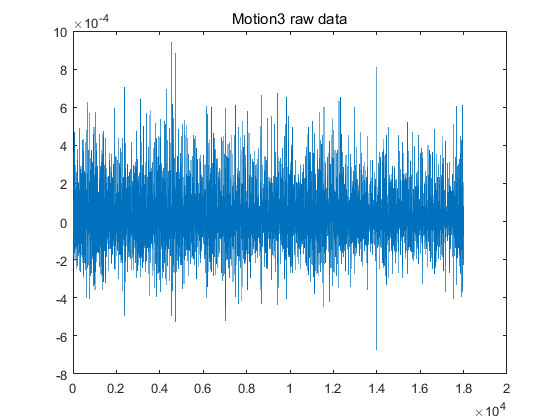

for n=1:size(Motion3Points,1)
    x{4} = [x{4}; ...
            sEMG_raw{nCh}(Motion3Points(n, 1):Motion3Points(n,2))];
end
figure;plot(x{4}); title('Motion3 raw data');  

  **4.5 Clipp Motion4 parts**

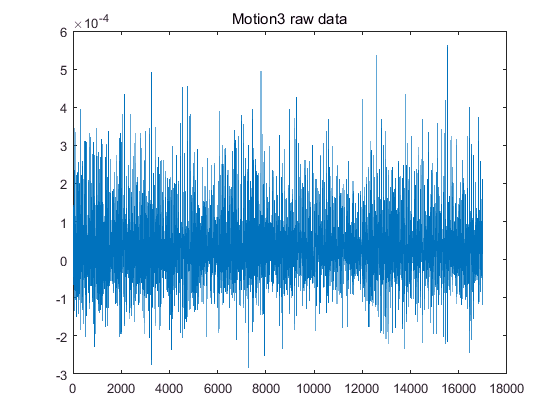

for n=1:size(Motion4Points,1)
    x{5} = [x{5}; ...
            sEMG_raw{nCh}(Motion4Points(n, 1):Motion4Points(n,2))];
end
figure;plot(x{5}); title('Motion3 raw data');  

**5. A new concise way to raw data clipping**

    from sEMG_raw{ch} to y={[], [], [], [], []}

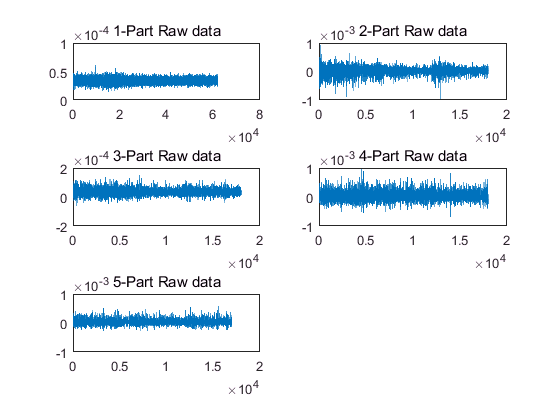

y = {[], [], [], [], []}; % clipped with concise nesting-for 
figure;
% nM - number of motions = 5, [Rest, Motion1, Motion2, Motion3, Motion4]
for nM=1:size(ClippedPoints, 2)
    for nR=1:size(ClippedPoints{nM},1)
        y{nM} = [y{nM}; ...
                 sEMG_raw{nCh}(ClippedPoints{nM}(nR, 1):ClippedPoints{nM}(nR, 2))];
    end
    subplot(3, 2, nM);
    plot(y{nM});title([num2str(nM), '-Part Raw data']);
end

**6. Pre-processing**

    6.1 denoising with built-in [wden]

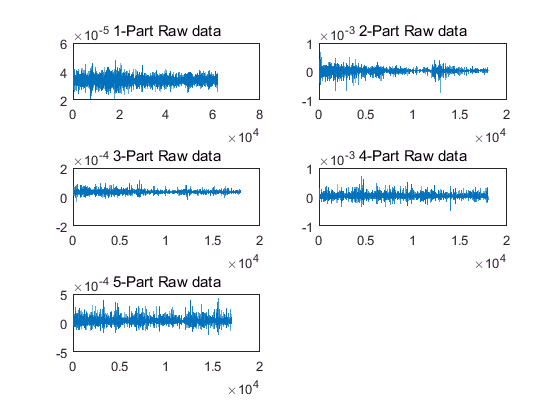

y_d = {[], [], [], [], []}; % denoised raw data
for n=1:size(y,2)
    y_d{n} = wden(y{n}, 'rigrsure', 's', 'mln', 5, 'sym4');
    subplot(3,2, n);
    plot(y_d{n});title([num2str(n), '-Part Raw data']);
end

**7.  Features extraction**

windows.LI = 64;     % length of incremental window
windows.LW = 128;    % length of time window
% FeatureName = {'IAV', 'MAX', 'NonZeroMed', 'NonZeroMedIndex'};
FeatureName = {'RMS', 'MAV','WL', 'MDF', 'MNF','MAX'};
% Rawdata2Sample(y_d{1}, windows,  FeatureName);
addpath('FeaturesExtraction');
for n=1:5
    sample{n} = Rawdata2Sample(y_d{n}, windows, FeatureName);
end

**8. Classification with LDA - linear discriminant analysis**

addpath('ReductionFunction');
%Splite sample data into 2 parts -- training&testing
[SampleTraining, SampleTesting] = Split2TrainTest(sample, 0.9);
[LDA_centers, LDA_matrix] = LDA_Reduction(SampleTraining, 3)

LDA reduction is being conducted.


nMotion = 5

LDA_centers =    -0.3039    0.0055   -0.0023
   -0.2677    0.1100    0.0375
   -0.2734    0.0118    0.0092
   -0.2377    0.1205   -0.0163
   -0.2380    0.1054   -0.0071


LDA_matrix =    1.0e+04 *

    0.1148    0.1258   -0.9213
   -1.0439   -0.1100    0.8759
    1.3378   -0.0739    0.7365
    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000
    0.0210    0.0001    0.0333


**9. Evaluation with the Testing Data set**

addpath('Evaluation');

Accuracy = DistanceEvaluate(SampleTesting, LDA_matrix, LDA_centers)

Accuracy =    97.0000    1.0000
   28.0000    0.1429
   28.0000    0.4643
   28.0000    0.5000
   27.0000    0.3333


average = Accuracy(:,1)'*Accuracy(:,2)/sum(Accuracy(:,1))

average = 0.6587

Accuracy = DistanceEvaluate(SampleTraining, LDA_matrix, LDA_centers)

Accuracy =   869.0000    0.9954
  251.0000    0.5737
  251.0000    0.7610
  251.0000    0.5378
  236.0000    0.3814


average = Accuracy(:,1)'*Accuracy(:,2)/sum(Accuracy(:,1))

average = 0.7670